**Exercicio 1 - aula 02/04/2024**

1) Determine a raiz real de $x^{3,5}=80, com o método das secantes até erro relativo seja 0,1% usando aproximações iniciais de $x_{0}=3$ e  $x_{1}=4$.

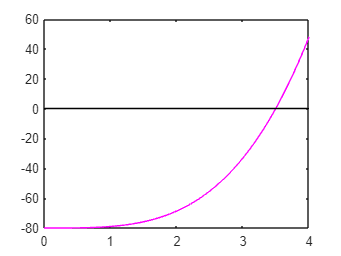

x= 0:0.01:4;
y = fun(x);
plot(x,y,'magenta')
y1 = 0*x;
hold on 
plot(x,y1, 'black')
hold off   


format long
x0 = 3;
x1 = 4;
 tol = 10^-4  %tolerancia 

tol =      1.000000000000000e-04


  k = 0;  %numero de interações
   er_rel = 0.1  %erro relativo inicial 

er_rel =    0.100000000000000


 while ( er_rel > tol)
     k = k+1; 
     x= (x0*fun(x1)-x1*fun(x0))/(fun(x1)- fun(x0)) ;  %Atualização pelo metodo das Secantes 
     xk(k, : ) = x;
     fk(k, : ) = fun(x);
     er_relk(k, :) = er_rel;
     x0 = x1;
     x1=x; 
     er_rel = abs(x1-x0)/abs(x1);
 end
 [xk, fk, er_relk]

ans =    3.409118979600672  -6.844403657695608   0.100000000000000
   3.482859014090345  -1.154732472324994   0.173323672167212
   3.497824731714683   0.037433597158881   0.021172270881867
   3.497354813421349  -0.000194527428150   0.004278578480118
   3.497357242774341  -0.000000032499685   0.000134363917419


**Definindo as funções que serão utilizadas:**

function f1 = fun(x)
    f1 = x.^3.5 - 80;
end